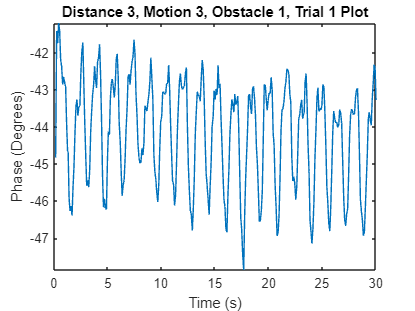

ans = 1.5330

clc; clear;

distance = 3;
motion = 3;
obstacle = 1;

for trial = 1:1

filename = sprintf("test_%i_%i_%i_%i.mat",distance,motion,obstacle,trial);
filename = fullfile(pwd,'/testing/matfiles',filename);
data = load(filename);
data = data.data;
t = data(:,1).Var1;
phase = data(:,2).Var2;

figure;
plot(t, phase);
axis([0 30 -inf inf])
%dist = distance * 0.2;
title(sprintf("Distance %i, Motion %i, Obstacle %i, Trial %i Plot", ...
               distance, motion, obstacle, trial));
xlabel("Time (s)")
ylabel("Phase (Degrees)")

toa_phase_calculate(filename,1,0.5,4,1,0.5,2)

end